Profundización II: Electromedicina

Nombre: Brandon Javier Rosero

Código: 219160289

clc
clear
close all

Cargar Imágen

I = imread('radiografia-de-torax.jpg');

Tranformación de intensidad

y1=0;
x1=0;
y2=25;
x2=63;
y3=130;
x3=121;
y4=200;
x4=210;
y5=255;
x5=255;

Pendientes

m1=(y2-y1)/(x2-x1);
m2=(y3-y2)/(x3-x2);
m3=(y4-y3)/(x4-x3);
m4=(y5-y4)/(x5-x4);
% m1=-1;
% m2=-1;
% m3=-1;
% m4=-1;

Interceptos

b1=y1-m1*x1;
b2=y2-m2*x2;
b3=y3-m3*x3;
b4=y4-m4*x4;
% b1=0;
% b2=0;
% b3=0;
% b4=0;

Aplicar transformación

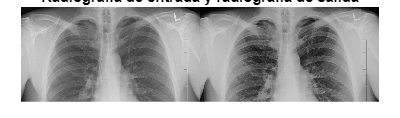

I1=rgb2gray(I);
[m,n]=size(I1);
Io=zeros(m,n);


for i=1:m
    for j=1:n
        p=I(i,j);
        if(p>=x1)&&(p <x2)
            Io(i,j)=m1*p+b1;
        elseif(p>=x2)&&(p <x3)
            Io(i,j)=m2*p+b2;
        elseif(p>=x3)&&(p <x4)
            Io(i,j)=m3*p+b3;
        else
            Io(i,j)=m4*p+b4;
        end
    end
end

imshow([I1 uint8(Io)]);
title("Radiografia de entrada y radiografia de salida")